# Section A: Data Preparation

### **Q1 :**

### Use the plot command to view the time series sensor data

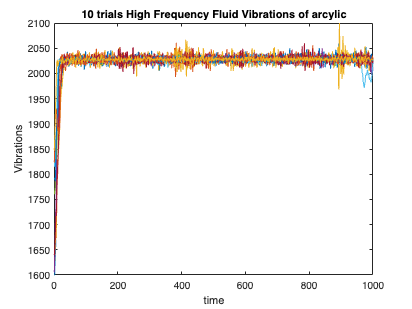

clear all;
close all;

testtime=500;

arc1=load('./source_data/PR_CW_DATA_2021/acrylic_211_01_HOLD.mat');
arc2=load('./source_data/PR_CW_DATA_2021/acrylic_211_02_HOLD.mat');
arc3=load('./source_data/PR_CW_DATA_2021/acrylic_211_03_HOLD.mat');
arc4=load('./source_data/PR_CW_DATA_2021/acrylic_211_04_HOLD.mat');
arc5=load('./source_data/PR_CW_DATA_2021/acrylic_211_05_HOLD.mat');
arc6=load('./source_data/PR_CW_DATA_2021/acrylic_211_06_HOLD.mat');
arc7=load('./source_data/PR_CW_DATA_2021/acrylic_211_07_HOLD.mat');
arc8=load('./source_data/PR_CW_DATA_2021/acrylic_211_08_HOLD.mat');
arc9=load('./source_data/PR_CW_DATA_2021/acrylic_211_09_HOLD.mat');
arc10=load('./source_data/PR_CW_DATA_2021/acrylic_211_10_HOLD.mat');

arc1V=arc1.F1pac(2,:);
arc2V=arc2.F1pac(2,:);
arc3V=arc3.F1pac(2,:);
arc4V=arc4.F1pac(2,:);
arc5V=arc5.F1pac(2,:);
arc6V=arc6.F1pac(2,:);
arc7V=arc7.F1pac(2,:);
arc8V=arc8.F1pac(2,:);
arc9V=arc9.F1pac(2,:);
arc10V=arc10.F1pac(2,:);

TV=[arc1V(testtime),arc2V(testtime),arc3V(testtime),arc4V(testtime),arc5V(testtime),arc6V(testtime),arc7V(testtime),arc8V(testtime),arc9V(testtime),arc10V(testtime)].';
figure(1)
plot(arc1V);hold on;
plot(arc2V);hold on;
plot(arc3V);hold on;
plot(arc4V);hold on;
plot(arc5V);hold on;
plot(arc6V);hold on;
plot(arc7V);hold on;
plot(arc8V);hold on;
plot(arc9V);hold on;
plot(arc10V);hold on;
title('10 trials High Frequency Fluid Vibrations of arcylic')
xlabel('time')
ylabel('Vibrations')

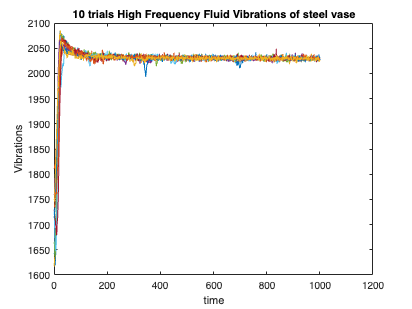


pp1=load('./source_data/PR_CW_DATA_2021/black_foam_110_01_HOLD.mat');
pp2=load('./source_data/PR_CW_DATA_2021/black_foam_110_02_HOLD.mat');
pp3=load('./source_data/PR_CW_DATA_2021/black_foam_110_03_HOLD.mat');
pp4=load('./source_data/PR_CW_DATA_2021/black_foam_110_04_HOLD.mat');
pp5=load('./source_data/PR_CW_DATA_2021/black_foam_110_05_HOLD.mat');
pp6=load('./source_data/PR_CW_DATA_2021/black_foam_110_06_HOLD.mat');
pp7=load('./source_data/PR_CW_DATA_2021/black_foam_110_07_HOLD.mat');
pp8=load('./source_data/PR_CW_DATA_2021/black_foam_110_08_HOLD.mat');
pp9=load('./source_data/PR_CW_DATA_2021/black_foam_110_09_HOLD.mat');
pp10=load('./source_data/PR_CW_DATA_2021/black_foam_110_10_HOLD.mat');

pp1V=pp1.F1pac(2,:);
pp2V=pp2.F1pac(2,:);
pp3V=pp3.F1pac(2,:);
pp4V=pp4.F1pac(2,:);
pp5V=pp5.F1pac(2,:);
pp6V=pp6.F1pac(2,:);
pp7V=pp7.F1pac(2,:);
pp8V=pp8.F1pac(2,:);
pp9V=pp9.F1pac(2,:);
pp10V=pp10.F1pac(2,:);


figure(2)
plot(pp1V);hold on;
plot(pp2V);hold on;
plot(pp3V);hold on;
plot(pp4V);hold on;
plot(pp5V);hold on;
plot(pp6V);hold on;
plot(pp7V);hold on;
plot(pp8V);hold on;
plot(pp9V);hold on;
plot(pp10V);hold on;
title('10 trials High Frequency Fluid Vibrations of steel vase')
xlabel('time')
ylabel('Vibrations')
hold off;

### **Q2:**

### **Merge measurements into a single tensor:**

**output: F1_PVT,   F1_E**

**size(F1_PVT) = H x W x D**

- D: 6, 6 different objects

- W: 3, 3 different dimentions (P, V, T)

- H: 10, 10 times of trials

**size(F1_E) = H x W x D**

- D: 6, 6 different objects

- W: 19 19 different dimentions 

- H: 10, 10 times of trials

% extract PVT
clc;clear;
mat_files = dir("./source_data/F1/*.mat");
F1_PVT = [];
for k = 1:length(mat_files)
    data = load(mat_files(k).name).Tall;
    data(:,[1,2]) = data(:,[2,1]); % swap VPT to PVT
    F1_PVT = cat(3,F1_PVT, data);
end
save("./F1_PVT.mat", "F1_PVT")

% Preprocessing the source files and extract Electrodes sensors data
clc;clear;
t = 30;
str = ["steel","kitchen","flour","car","black","acrylic"];
mat_files = dir("./source_data/PR_CW_DATA_2021/*.mat");
names = [];
for i = 1:length(mat_files)
    names = [names, mat_files(i).name];
end

F1_E = [];
for m = 1:length(str)
    single_obj = [];
    for n = 1:length(mat_files)
        if contains(mat_files(n).name, str(m))
            data = load(mat_files(n).name).F1Electrodes;
            data = data(:,t);
            data = data.';
            single_obj = cat(1, single_obj, data);
        end
    end
    F1_E = cat(3, F1_E,single_obj);
end
save("./F1_E.mat", "F1_E")

## **Q3:**

**3D Plot**

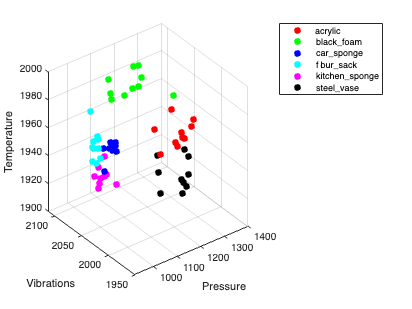

clc;clear;
cla('reset');
load("F1_PVT.mat")
colors = ["r", "g", "b", "c", "m", "k"];
str = ["acrylic","black\_foam","car\_sponge","flour\_sack","kitchen\_sponge","steel\_vase"];
shape = size(F1_PVT);

for m = 1 : shape(3)
    x = F1_PVT(:,1,m);
    y = F1_PVT(:,2,m);
    z = F1_PVT(:,3,m);
    plot3(x,y,z,'.','color',colors(m),'MarkerSize',20);
    hold on;
end

grid on;
xlabel('Pressure');
ylabel('Vibrations');
zlabel("Temperature");
legend(str);